# Homework 2

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc

## Problem #1 - Trajectory of a toy missile 

**a) Plot the equation as a function of **$\theta_0$

y0 = 1.3;
v0 = 70;
g = 3.721;
x = 290;
h = 3.4;

thetaDeg = [5,85]; 

a0 = @() y0;
a1 = @(a) tand(a);
a2 = @(a) -(g/2)./((v0.^2).*cosd(a).^2);

f = @(a) a2(a).*x.^2 + a1(a).*x + a0() - h;

figure()
fplot(f, thetaDeg)
title("HW2.1.a")
xlabel("\theta [Degrees]")
ylabel("f(\theta)")
grid on
hold on

**b) How many solutions exist?**

**     2**

**c) Table of angles that will allow the missile to hit the target**

guess_bisect_1 = bisect(f, 0, 10);
guess_bisect_2 = bisect(f, 80, 90);
guess_fzero_1 = fzero(f, 5);
guess_fzero_2 = fzero(f, 80);
fprintf("Zero #    Bisect     Fzero\n" + ...
        "------ --------- ---------\n" + ...
        "   1   %9.6f %9.6f\n" + ...
        "   2   %9.6f %9.6f\n", guess_bisect_1, guess_fzero_1, guess_bisect_2, guess_fzero_2)

Zero #    Bisect     Fzero
------ --------- ---------
   1    6.781173  6.781172
   2   83.633652 83.633721


**d) Plot the solutions from part c into the plot from part a**

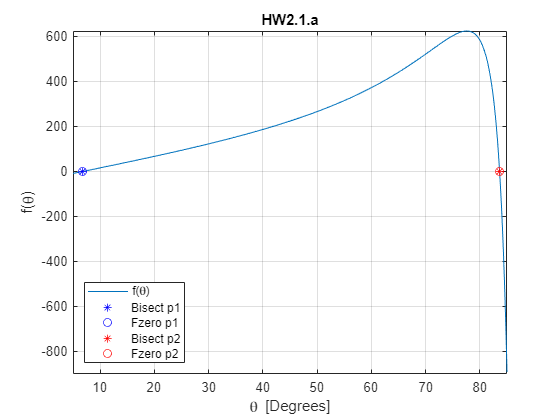

plot(guess_bisect_1, f(guess_bisect_1), "b*", guess_fzero_1, f(guess_fzero_1), "bo", ...
     guess_bisect_2, f(guess_bisect_2), "r*", guess_fzero_2, f(guess_fzero_2), "ro")
legend("f(\theta)", "Bisect p1", "Fzero p1", "Bisect p2", "Fzero p2","location", "southwest")
hold off

**e) Plot the trajectory of the toy missile**

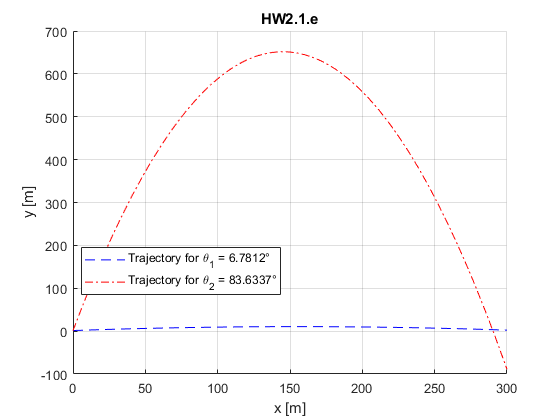

ax1 = guess_fzero_1;
fx1 = @(x) a2(ax1).*x.^2 + a1(ax1).*x + a0();
ax2 = guess_fzero_2;
fx2 = @(x) a2(ax2).*x.^2 + a1(ax2).*x + a0();

figure()
hold on
fplot(fx1, [0,300], "b--") 
fplot(fx2, [0,300], "r-.") 
grid on
title("HW2.1.e")
xlabel("x [m]")
ylabel("y [m]")
str1 = ['Trajectory for \theta_1 = ' num2str(ax1) '°'];
str2 = ['Trajectory for \theta_2 = ' num2str(ax2) '°'];
legend(str1, str2, "location", "best")

## Problem #2 - Bisect vs. False position

**a) Plot the function **

**b) Compute the root.  Display the results in a table. Explain the difference**

**Explain the difference in the number of iterations between the two methods**

EXPLANATION HERE

**c) Compute the root.  Display the results in a table. Explain the difference**

**Explain the difference in the number of iterations between part b and part c**

EXPLANATION HERE

**d) Plot all solutions from part b and c in the figure from part a**

## Problem #3 - Newton-Raphson

**a) Display the vector as a column vector**

**b) Calculate the exact real root using the roots function.  **

**c) Why does the Newton-Raphson method initially overshoot the exact value and then increase (or decrease) ot converge to the exact value?**

ANSWER HERE

## Problem #4 - Baseball trajectory

**a) Plot the function**

**b) Will the catcher catch the ball?  **

**c) Compute the maximum height reached**

**    i) Golden section search**

**    ii) Parabolic interpolation**

**    iii) MATLAB's fminbnd**

## Problem #5 - 2D Optimization

**a) 3D plot of function**

**b) 1st initial guess, find maximum, display in fprintf**

**c) plot maximum on plot from part a)**

**d) 2nd initial guess, find max and add to plot from part a)**

**e) What changes between the two different initial guesses and why?**

ANSWER HERE

## Helper functions

### Bisect function

### False position function

### Golden-section search function

### Parabolic interpolation function